fprintf("PLEASE SELECT AN IMAGE\n")

PLEASE SELECT AN IMAGE


i=uigetfile('*.*');
j=imread(i)

j = 2160×3240×3 uint8 array
j(:,:,1) =

  Columns 1 through 1,666

    28    28    28    28    28    28    28    28    29    29    29    29    29    29    29    29    28    28    28    28    28    28    28    28    27    27    27    28    28    29    29    29    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    28    27    27    27    28    28    29    29    29    28    28    28    28    28    28    28    28    29    29    29    29    29    29    29    29    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    26    26    26    26    26    26    26    26    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    28    27    27    26    26    27    27    28    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27   

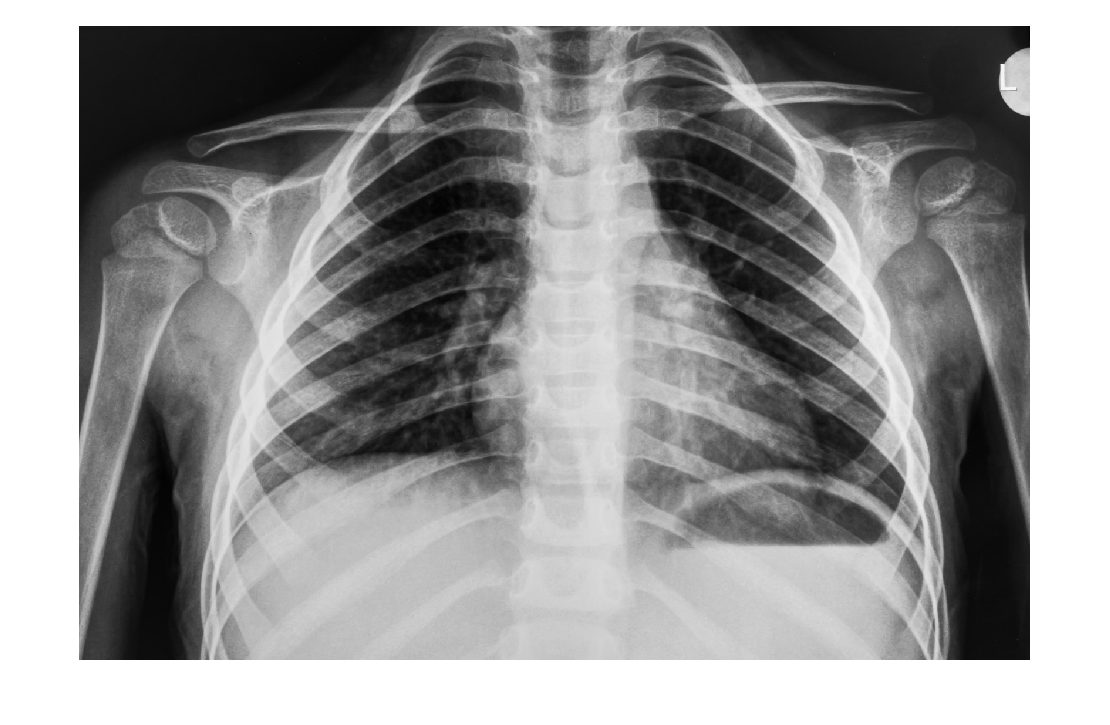

k=rgb2gray(j);
imshow(k)

[r,c]=size(k)

r = 2160

c = 3240

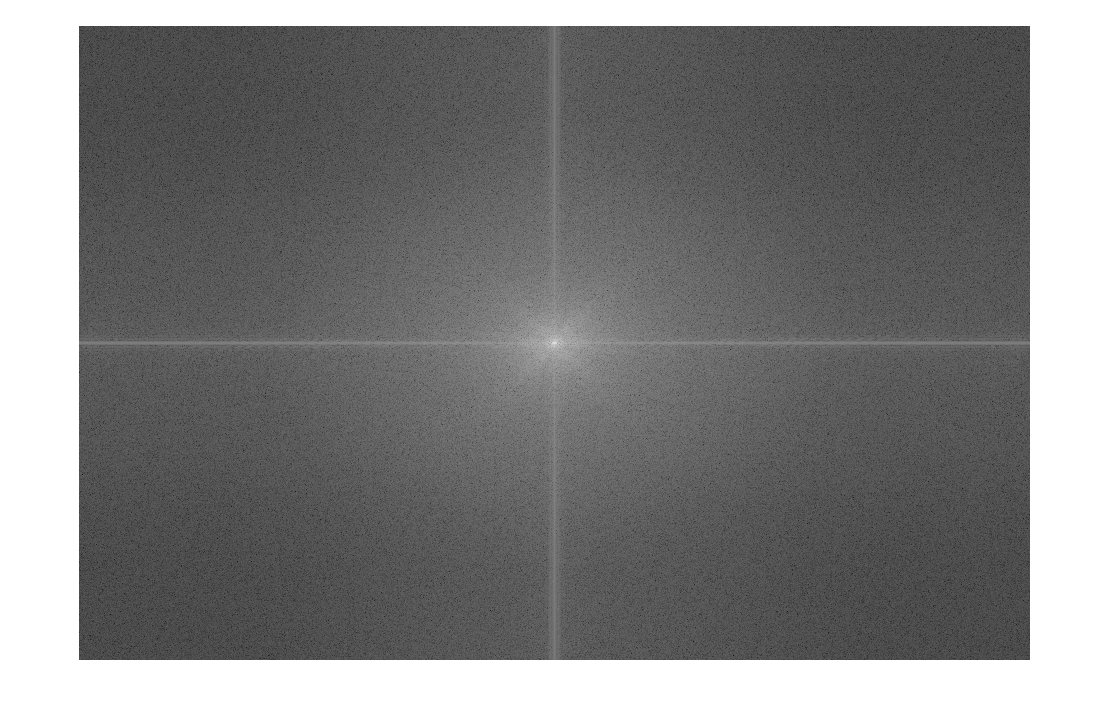

l=fft2(k);
m=fftshift(l);
n=abs(m);
o=log(1+n);
imshow(o,[]);

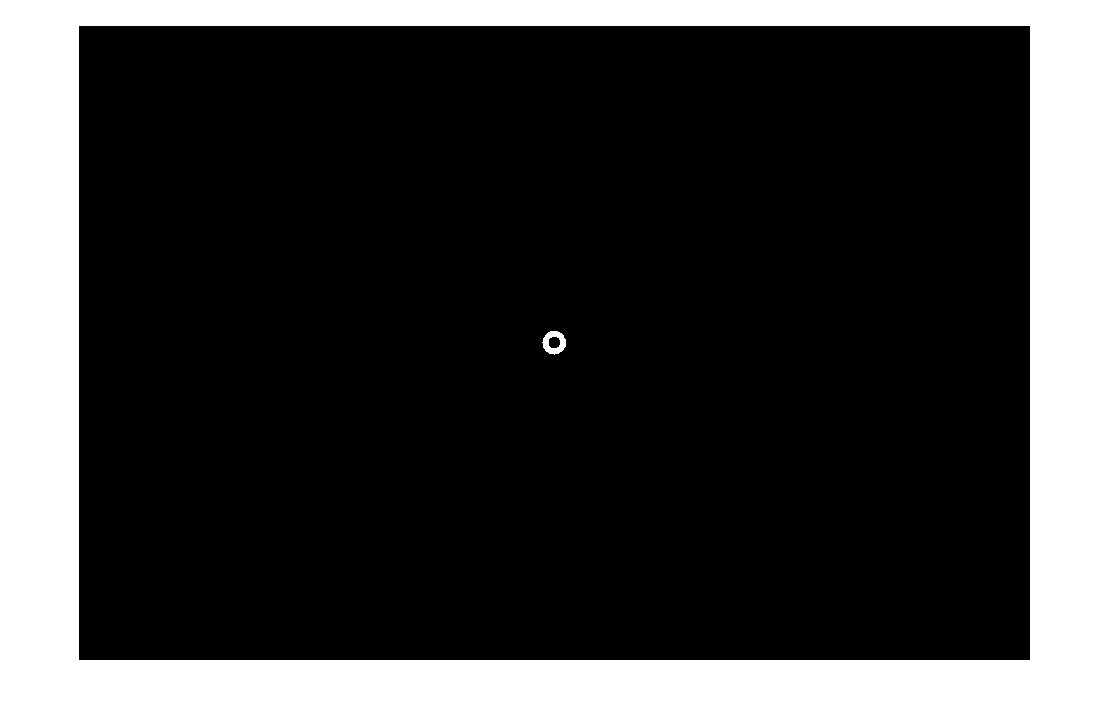

Z=zeros(r,c);
for R=1:r
    for C=1:r
        if (R-r/2)^2+(C-c/2)^2 >= 20^2
            if (R-r/2)^2+(C-c/2)^2 <= 40^2
                Z(R,C)=1;
            end
        end
    end
end


imshow(Z)

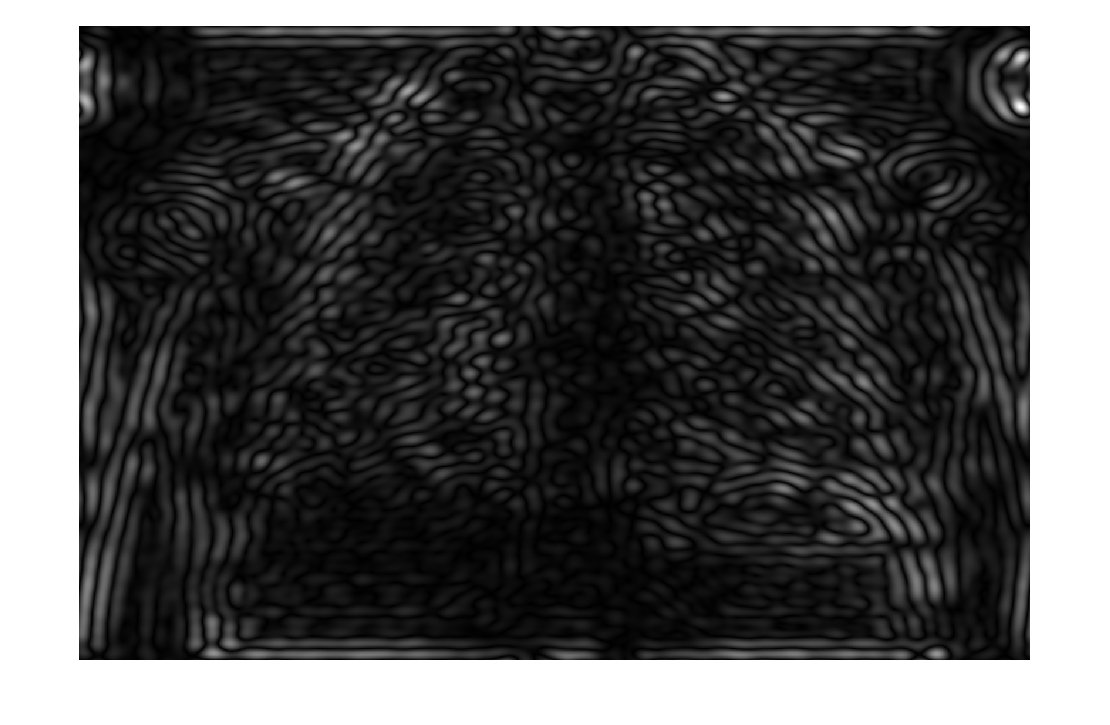

new=m.*Z;
new1=fftshift(new);
new2=ifft2(new1);
imshow(abs(new2),[]);

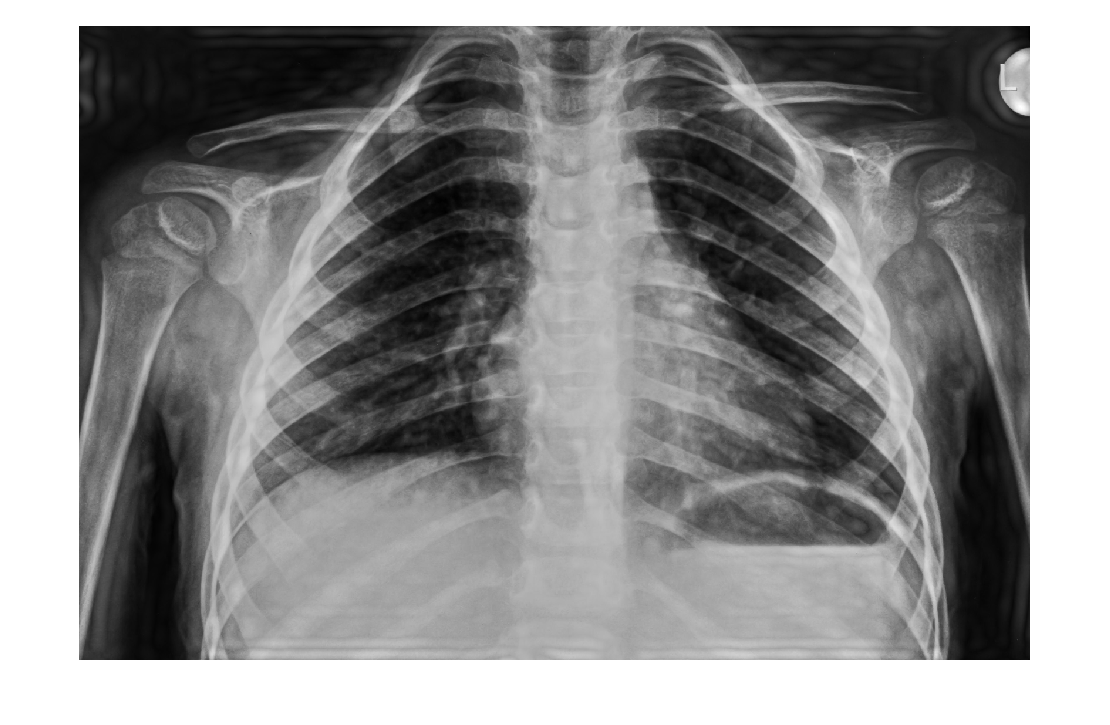

edge=abs(new2);
sharp=double(k)+edge;
imshow(sharp,[]);